# Simple Hebbian and Oja Rule Simulations

The code in this document is meant to Simulate the Simple Hebbian and Oja Rules under 4 different input schemes. in all cases, weights and inputs are in four dimensions.

- Just noise as input. Each input dimension is sampled uniformly from 0 to 1.

- Just patterned input, each input is 0.1, except for that in dimension 1 which is equal to 5.

- 95% noise and 5% patterned input. Inputs are described above but each is randomly sampled, with noise being sampled with probability 0.95.

- The last simulation stimulates the neuron with solely patterned input then noise for the remainder,  after enough time, the neurons are occasionally triggered by the pattern again to test their abilities to recall it.

Also available in this document are functions for the Hebbian and Oja update rules.

## The Rules React on Noise-As-Input

Each input is randomly sampled from ~Unif(0,1).

% Define parameters
n_iters = 10^5;
eta = .0001;

eta = 1.0000e-04

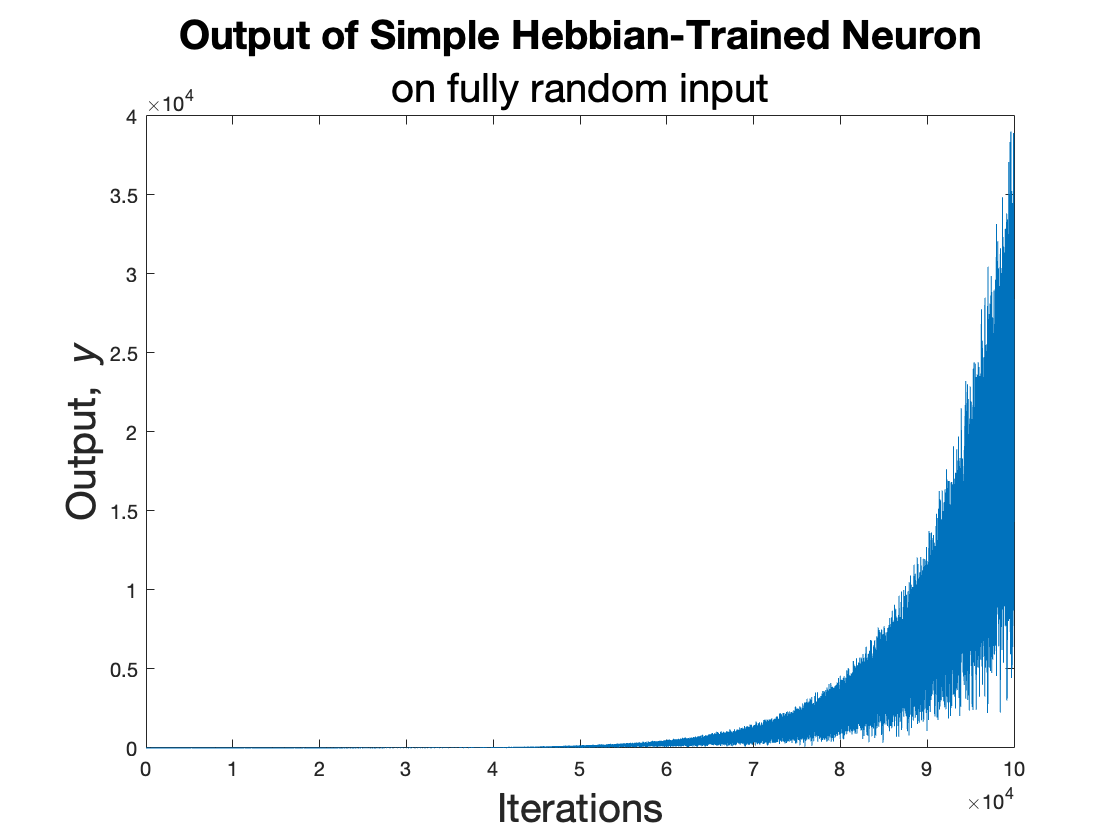

eta = 10^-4;

% initialize weights identically for both rules
w_hebb = rand([4 1]);
w_oja = w_hebb;

% variables to hold weights over time for both rules
hebb_history = NaN([4, n_iters]);
oja_history = NaN([4, n_iters]);

% For the outputs over time:
oja_out = NaN(n_iters,1);
hebb_out = NaN(n_iters,1);

for i = 1:n_iters
    % generate random input:
    x = rand([4 1]);
    
    % Update the hebbian parameters:
    y_hebb = w_hebb' * x;
    hebb_out(i) = y_hebb;
    w_hebb = hebbian(w_hebb, x, y_hebb, eta);
    hebb_history(:,i) = w_hebb;
    
    % Update the Oja parameters:
    y_oja = w_oja' * x;
    oja_out(i) = y_oja;
    w_oja = oja(w_oja, x, y_oja, eta);
    oja_history(:,i) = w_oja;
    
    % Update the BCM parameters
    y_BCM = w_BCM' * x;
    if i == 1
        theta = y_BCM;
    else
        theta = theta_update(theta, eta_theta, y_BCM);
    end
    BCM_out(i) = y_BCM;
    w_BCM = BCM(w_BCM, x, y_BCM, theta, eta_w, eta_null);
    BCM_history(:,i) = w_BCM;
end
% Plot the outputs of each model:
figure;
plot(1:n_iters, hebb_out);
title("Output of Simple Hebbian-Trained Neuron", "FontSize", 20)
xlabel("Iterations", "FontSize",20)
ylabel("Output, {\it y}", "FontSize",20)
subtitle("on fully random input", "FontSize", 20)

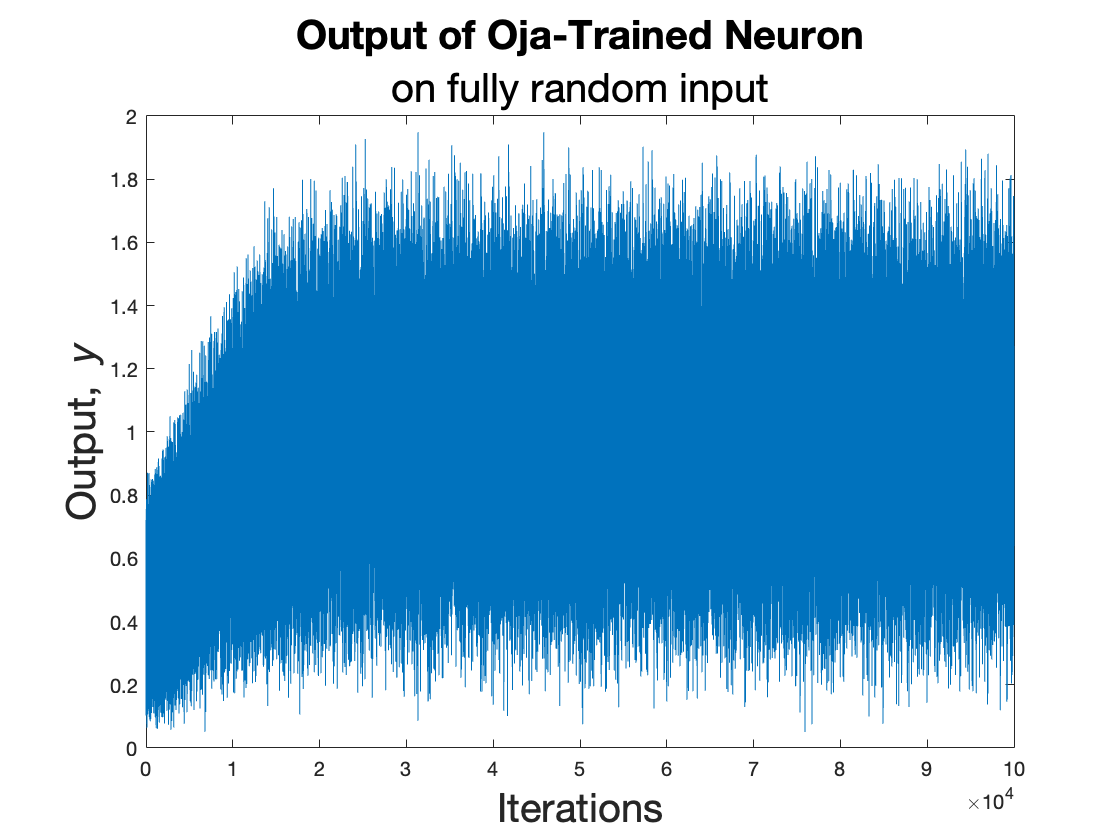

plot(1:n_iters, oja_out);
title("Output of Oja-Trained Neuron", "FontSize", 20)
subtitle("on fully random input", "FontSize", 20)
xlabel("Iterations", "FontSize",20)
ylabel("Output, {\it y}", "FontSize",20)

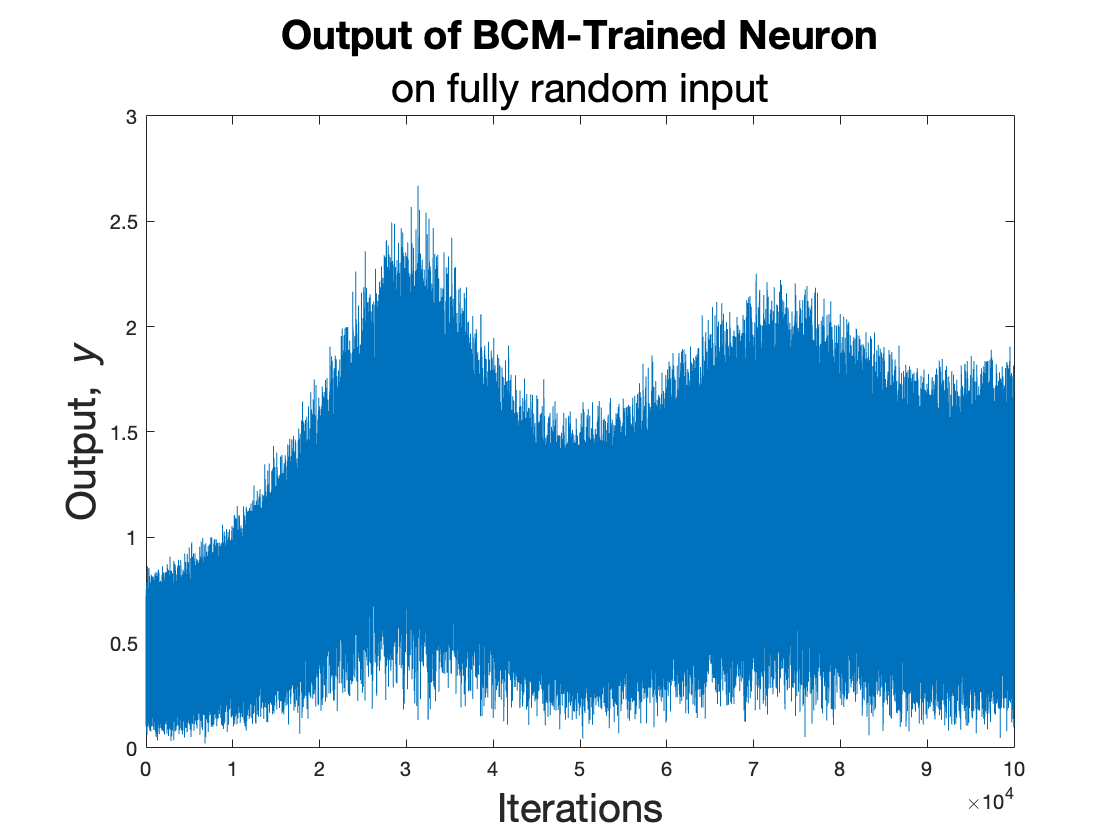


% Plot the weights of each model:

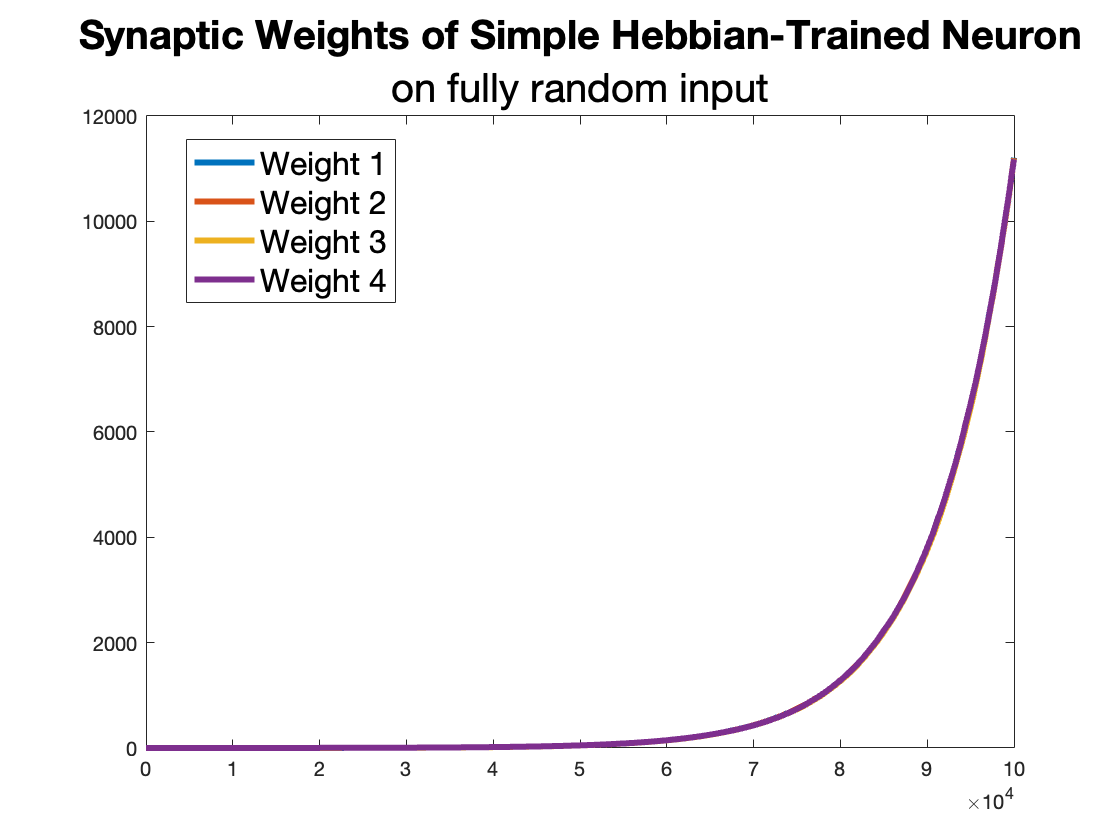

figure;
for p = 1:4
    plot(1:n_iters, hebb_history(p,:), 'LineWidth', 3);
    hold on;
end
title("Synaptic Weights of Simple Hebbian-Trained Neuron", "FontSize", 20)
subtitle("on fully random input", "FontSize",20)
legend("Weight 1", "Weight 2", "Weight 3", "Weight 4", "FontSize", 16, "location", "best")

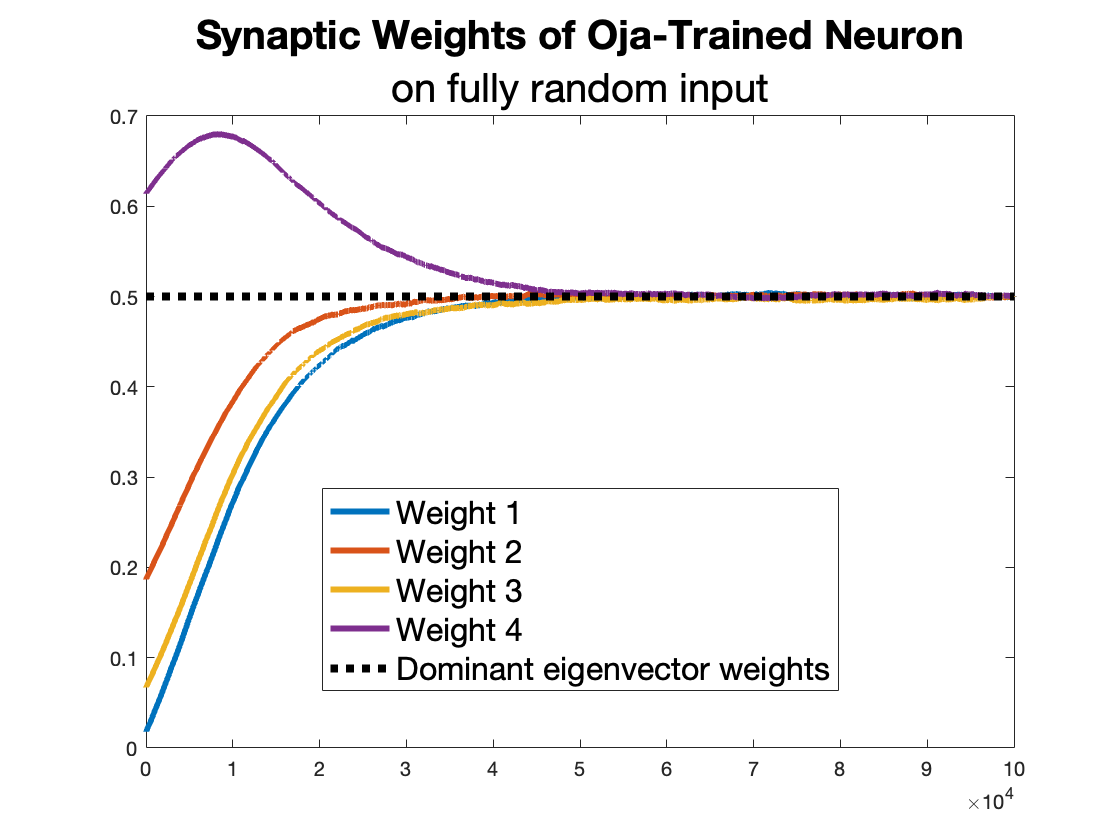

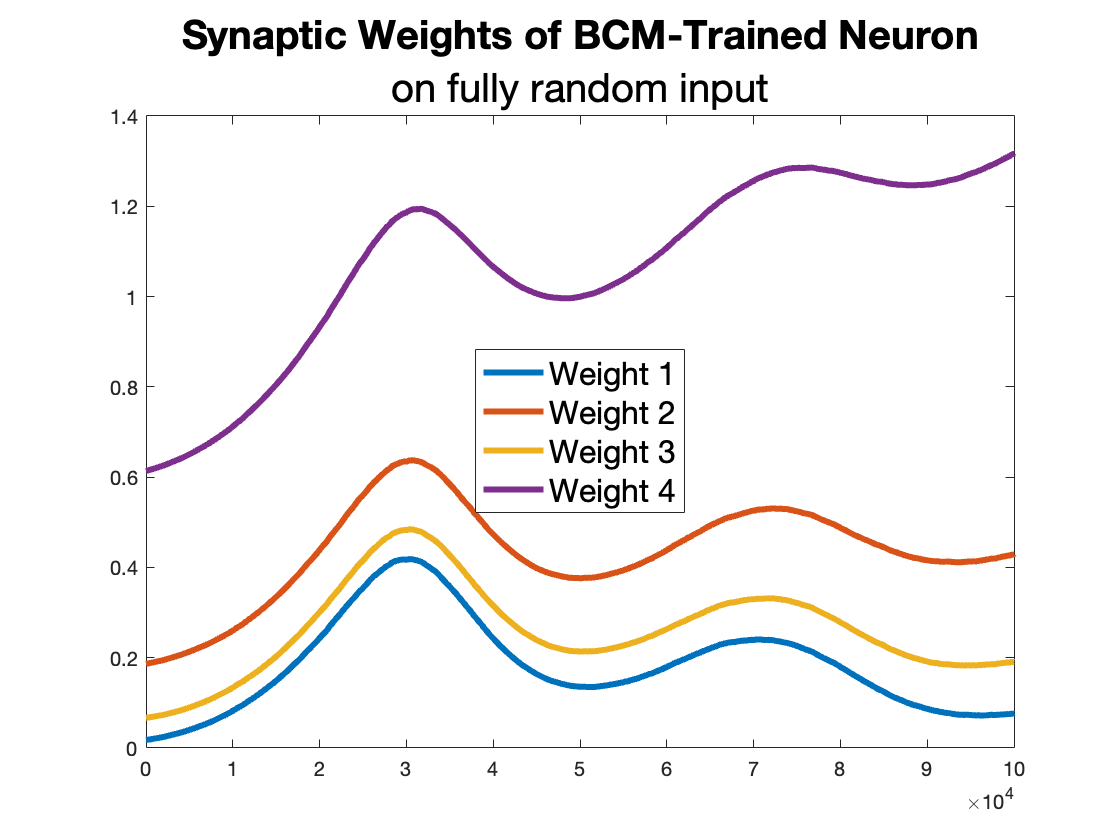

figure;
for p = 1:4
    plot(1:n_iters, oja_history(p,:), 'LineWidth', 3);
    hold on;
end
plot( 1:n_iters,0.5 * ones([n_iters,1]), 'LineStyle', ':', 'LineWidth',4, "Color","black") 
title("Synaptic Weights of Oja-Trained Neuron", "FontSize", 20)
subtitle("on fully random input", "FontSize",20)
legend("Weight 1", "Weight 2", "Weight 3", "Weight 4", "Dominant eigenvector weights", "FontSize", 16, "location", "best")

## The Rules React to Solely Patterned Input

Just patterned input, each input is 0.1, except for that in dimension 1 which is equal to 5.

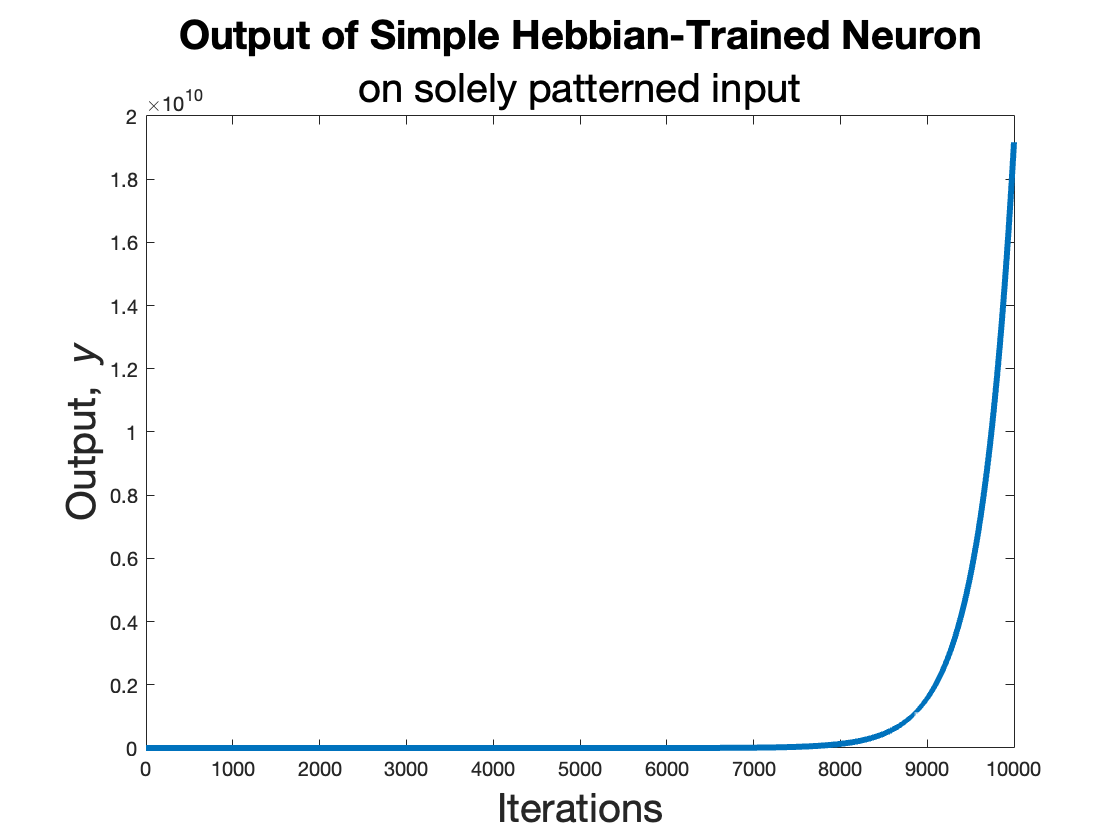

% Define parameters
n_iters = 10^4;
eta = 10^-4;

% initialize all weights the same
w_hebb = rand([4 1]);
w_oja = w_hebb;

% For keeping track of output
oja_out = NaN(n_iters,1);
hebb_out = NaN(n_iters,1);

% For keeping track of weights:
hebb_history = NaN([4, n_iters]);
oja_history = NaN([4, n_iters]);

%SIMULATE
for i = 1:n_iters
    x = [5; 0.1; 0.1; 0.1];
    
    % Update the hebbian parameters:
    y_hebb = w_hebb' * x;
    hebb_out(i) = y_hebb;
    w_hebb = hebbian(w_hebb, x, y_hebb, eta);
    hebb_history(:,i) = w_hebb;
    
    % Update the Oja parameters:
    y_oja = w_oja' * x;
    oja_out(i) = y_oja;
    w_oja = oja(w_oja, x, y_oja, eta);
    oja_history(:,i) = w_oja;
    
end
% Plot the outputs of each rule:
figure;
plot(1:n_iters, hebb_out, 'LineWidth', 3);
title("Output of Simple Hebbian-Trained Neuron", "FontSize", 20)
subtitle("on solely patterned input", "FontSize", 20)
xlabel("Iterations", "FontSize",20)
ylabel("Output, {\it y}", "FontSize",20)

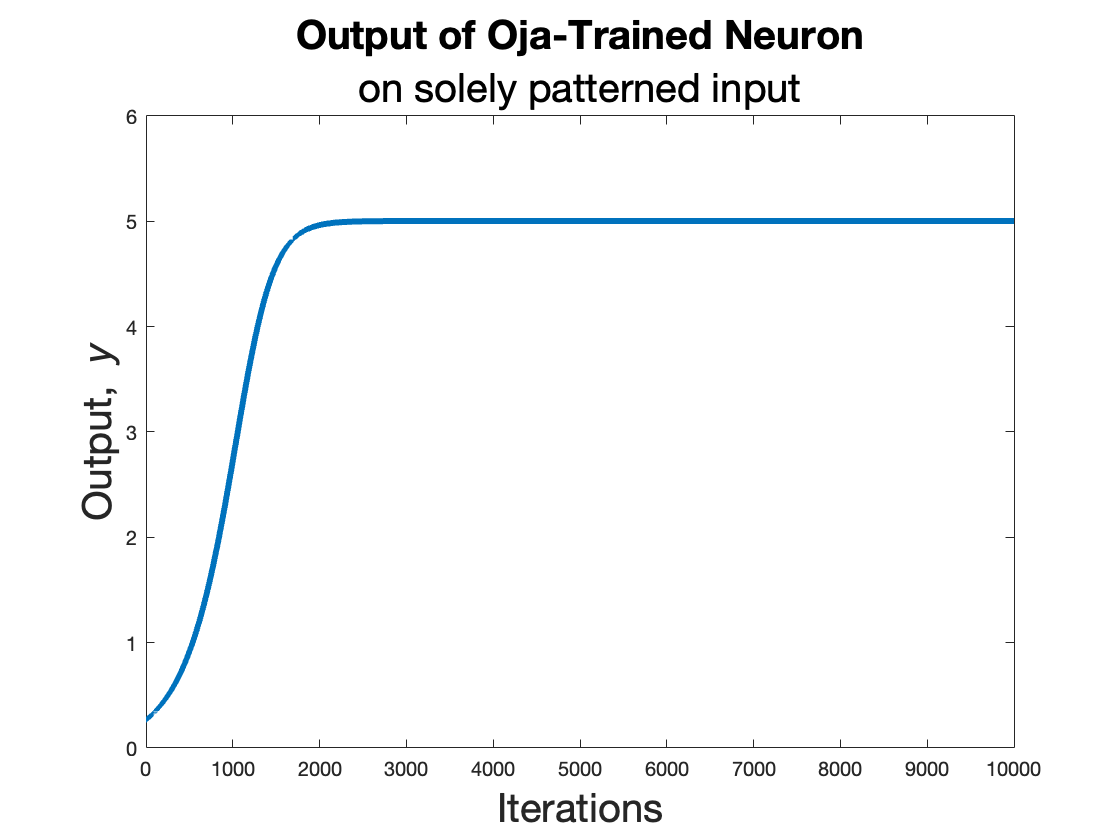

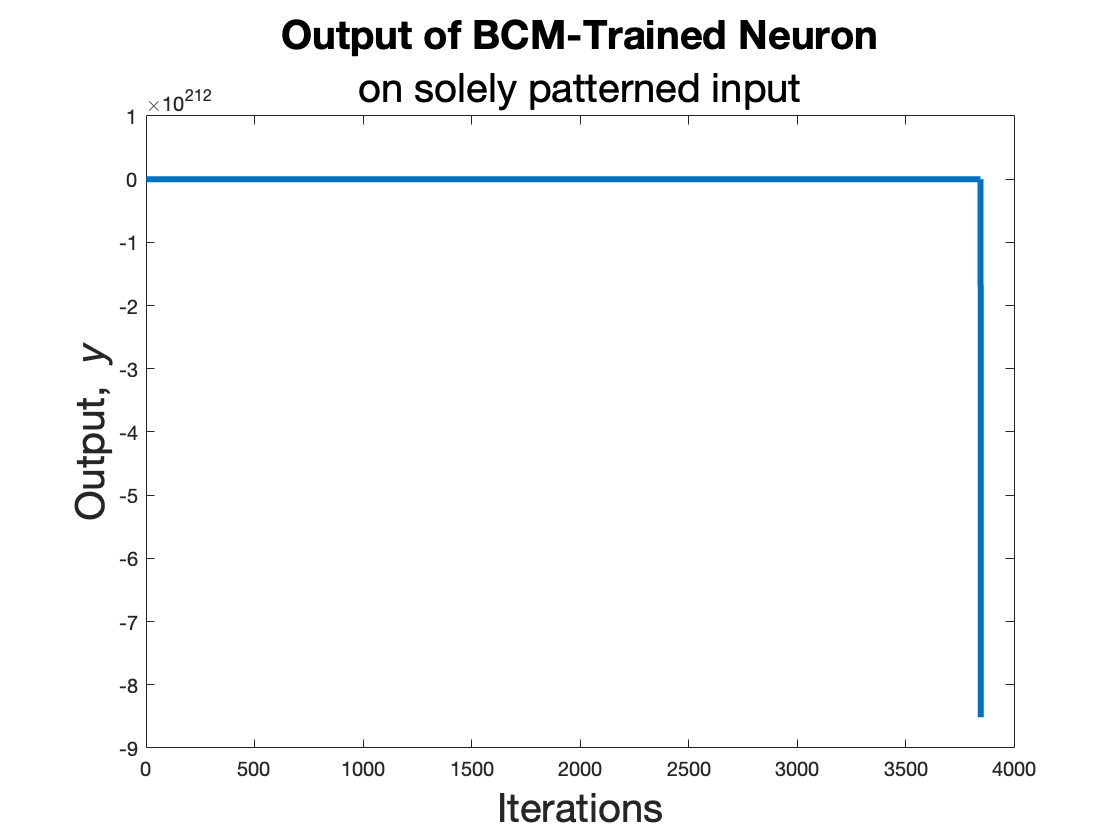

plot(1:n_iters, oja_out, 'LineWidth', 3);
title("Output of Oja-Trained Neuron", "FontSize", 20)
subtitle("on solely patterned input", "FontSize", 20)
xlabel("Iterations", "FontSize",20)
ylabel("Output, {\it y}", "FontSize",20)

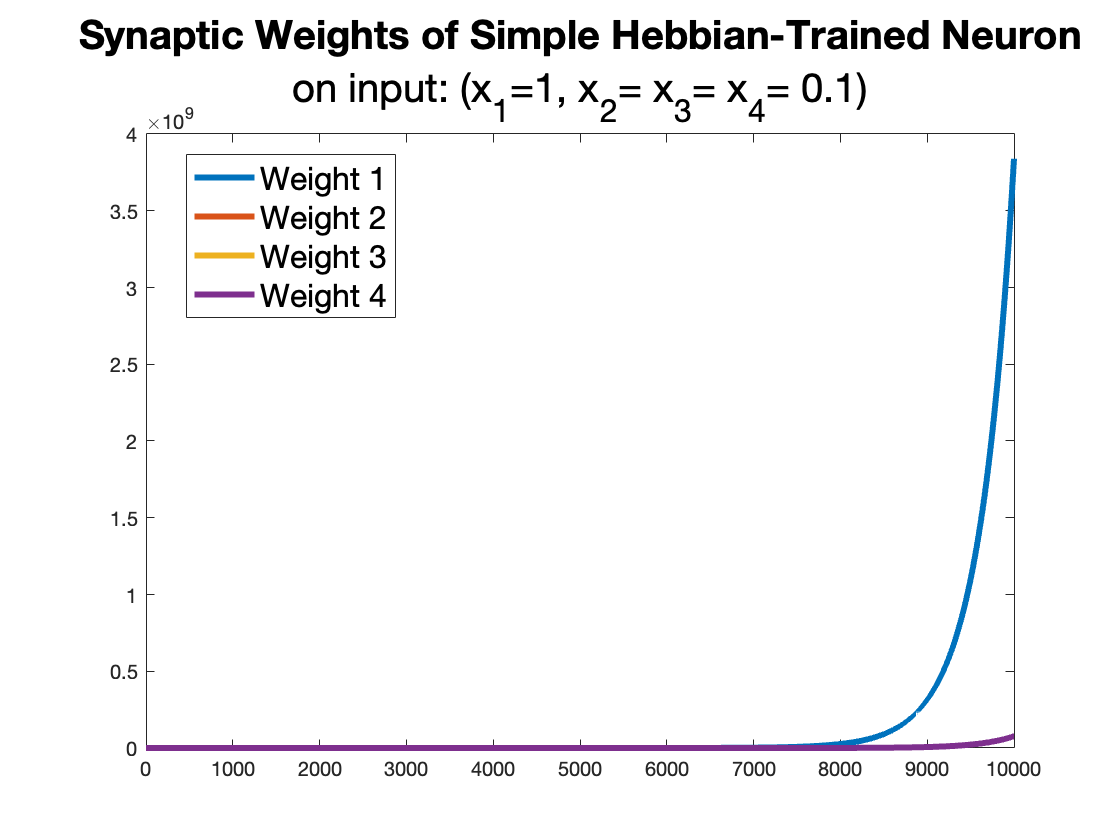

    
% Plot the weights over time of each model:
figure;
for p = 1:4
    plot(1:n_iters, hebb_history(p,:), 'LineWidth', 3);
    hold on;
end
title("Synaptic Weights of Simple Hebbian-Trained Neuron", "FontSize", 20)
subtitle("on input: (x_1=1, x_2= x_3= x_4= 0.1)", "FontSize",20)
legend("Weight 1", "Weight 2", "Weight 3", "Weight 4", "FontSize", 16, "location", "best")

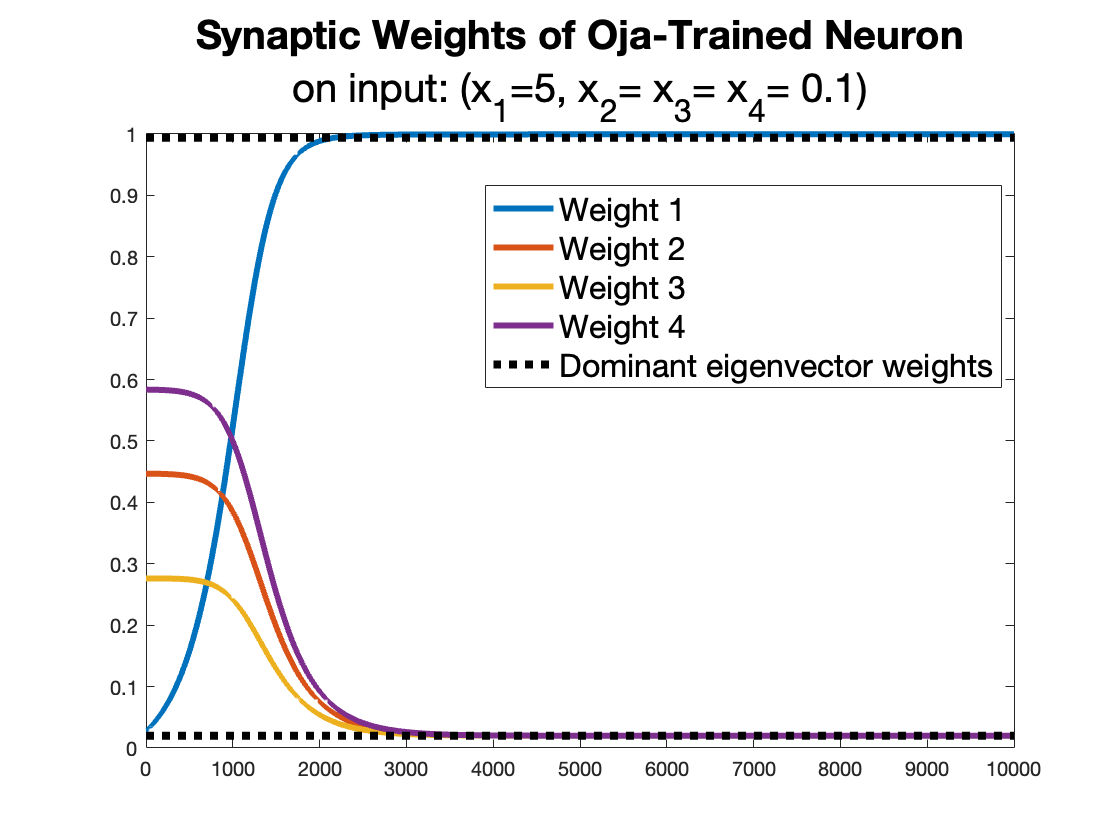

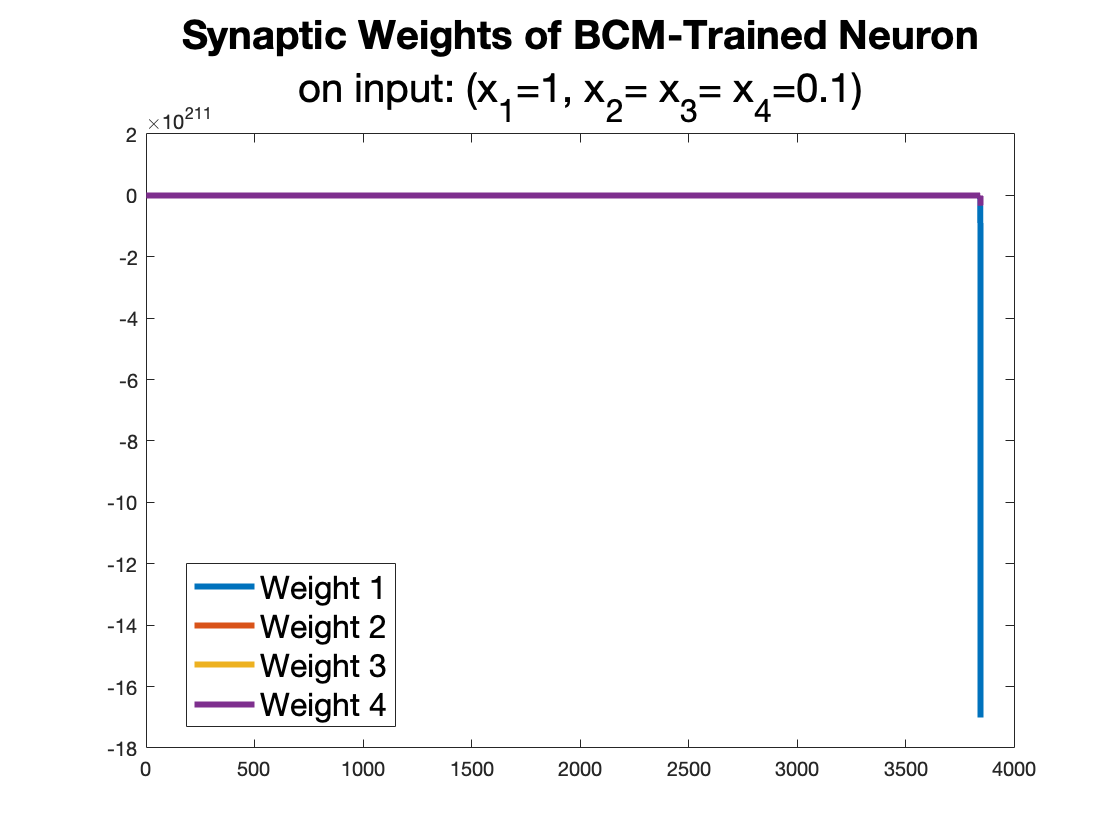

figure;
for p = 1:4
    plot(1:n_iters, oja_history(p,:), 'LineWidth', 3);
    hold on;
end
plot( 1:n_iters,0.994 * ones([n_iters,1]), 'LineStyle', ':', 'LineWidth',4, "Color","black") 
plot( 1:n_iters,0.02 * ones([n_iters,1]), 'LineStyle', ':', 'LineWidth',4, "Color","black") 
title("Synaptic Weights of Oja-Trained Neuron", "FontSize", 20)
subtitle("on input: (x_1=5, x_2= x_3= x_4= 0.1)", "FontSize",20)
legend("Weight 1", "Weight 2", "Weight 3", "Weight 4", "Dominant eigenvector weights", "FontSize", 16, "location", "best")

### Partially Patterned Input

95% noise and 5% patterned input. Inputs are described above but each is randomly sampled, with noise being sampled with probability 0.95.

% Initialize all weights across models identically:
w_hebb = rand([4 1]);
w_oja = w_hebb;

% Define parameters:
eta = 10^-2

eta = 0.0100

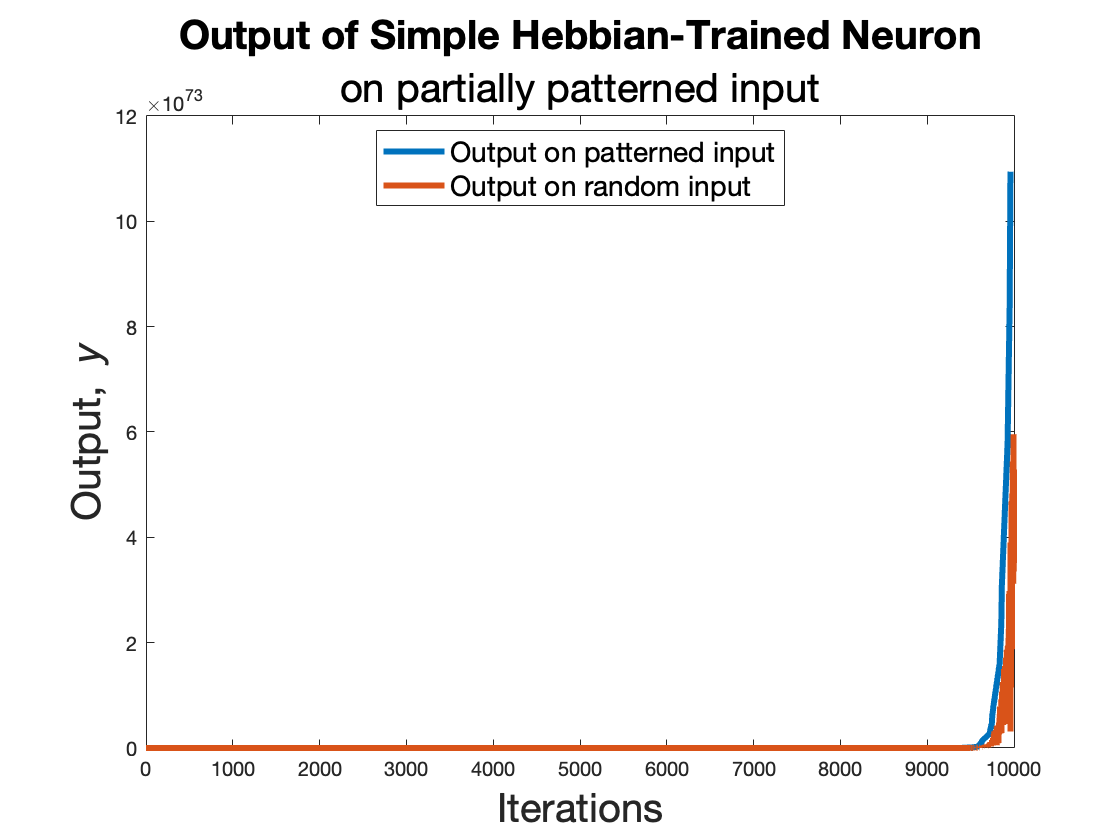

n_iters = 10000;

% For keeping track of otuput
oja_out = NaN(n_iters,1);
hebb_out = NaN(n_iters,1);
BCM_out = NaN(n_iters,1);

% For keeping track of weights:
hebb_history = NaN([4, n_iters]);
oja_history = NaN([4, n_iters]);
BCM_history = NaN([4, n_iters]);

% For keeping track of when random input vs. when pattern input occurs:
x1_indices = [];
rand_indices = [];

%SIMULATE
for i = 1:n_iters
    
    seed = rand;
    if rand < 0.05 % 5% of the time give this patterned input
        x1_indices(end+1) = i;
        x = [5 ; 0.1; 0.1; 0.1];
    else % 95% of the time give it random noise
        x = rand([4 1]);
        rand_indices(end+1) = i;
    end
    
    % Update the hebbian parameters:
    y_hebb = w_hebb' * x;
    hebb_out(i) = y_hebb;
    w_hebb = hebbian(w_hebb, x, y_hebb, eta);
    hebb_history(:,i) = w_hebb;
    
    % Update the Oja parameters:
    y_oja = w_oja' * x;
    oja_out(i) = y_oja;
    w_oja = oja(w_oja, x, y_oja, eta);
    oja_history(:,i) = w_oja;
end
% Plot the outputs over time
figure;
plot(x1_indices, hebb_out(x1_indices), "LineWidth",3)
hold on;
plot(rand_indices, hebb_out(rand_indices), "LineWidth",3)
title("Output of Simple Hebbian-Trained Neuron", "FontSize", 20)
subtitle("on partially patterned input", "FontSize", 20)
xlabel("Iterations", "FontSize",20)
ylabel("Output, {\it y}", "FontSize",20)
legend("Output on patterned input", "Output on random input", "FontSize",14, "location", "best")

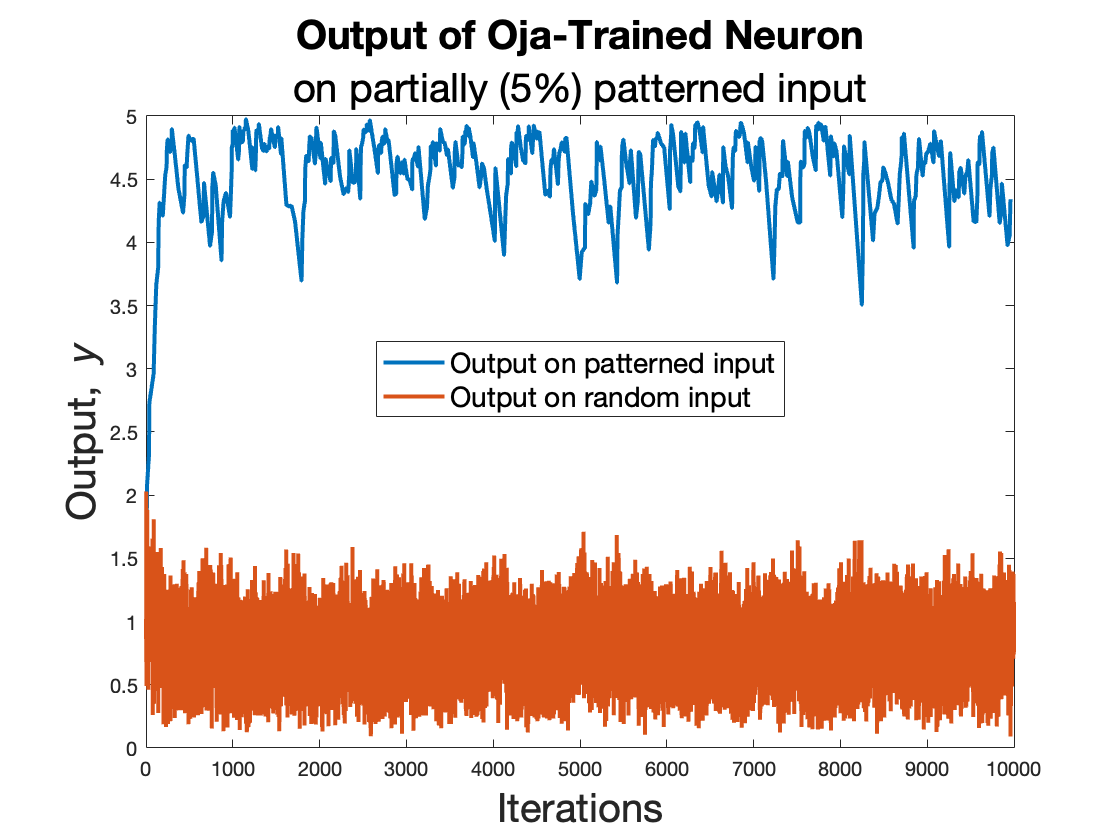

figure;
plot(x1_indices, oja_out(x1_indices), "LineWidth",2)
hold on;
plot(rand_indices, oja_out(rand_indices), "LineWidth",2)
title("Output of Oja-Trained Neuron", "FontSize", 20)
subtitle("on partially (5%) patterned input", "FontSize", 20)
xlabel("Iterations", "FontSize",20)
ylabel("Output, {\it y}", "FontSize",20)
legend("Output on patterned input", "Output on random input", "FontSize",14, "location", "best")

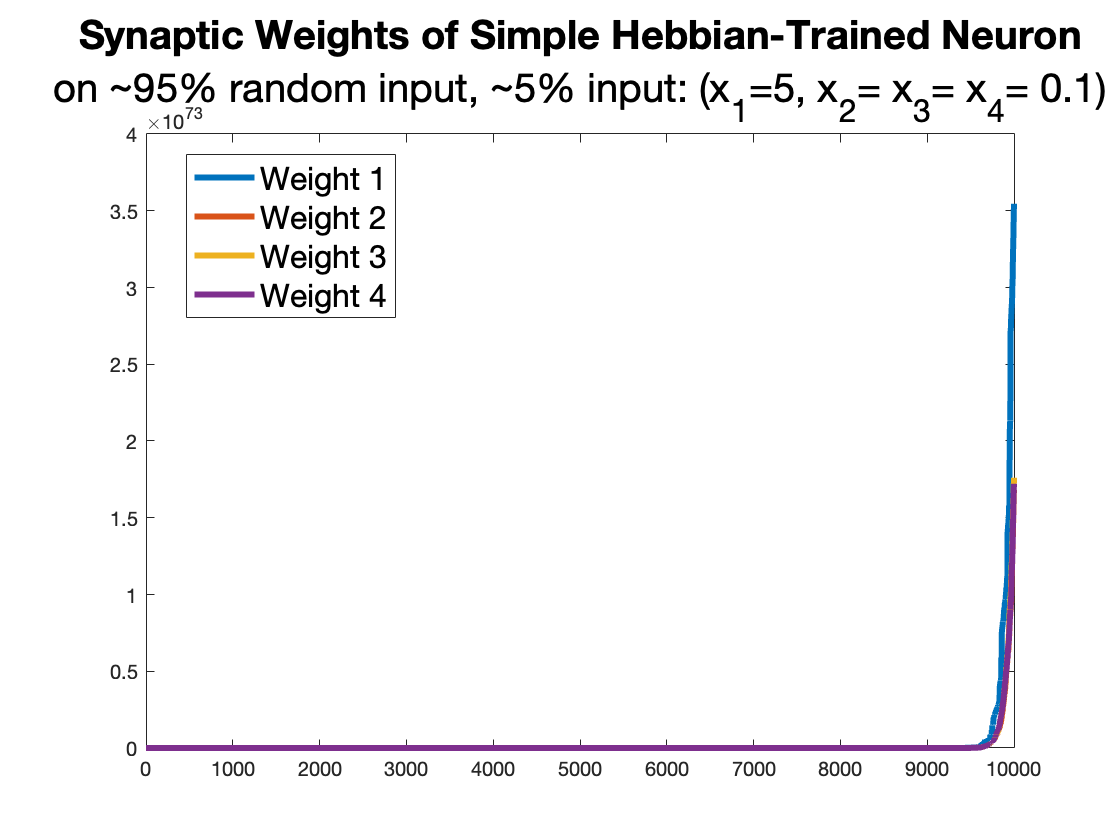

    
% Plot the weights of the rules over time
figure;
for p = 1:4
    plot(1:n_iters, hebb_history(p,:), 'LineWidth', 3);
    hold on;
end
title("Synaptic Weights of Simple Hebbian-Trained Neuron", "FontSize", 20)
subtitle("on ~95% random input, ~5% input: (x_1=5, x_2= x_3= x_4= 0.1)", "FontSize",20)
legend("Weight 1", "Weight 2", "Weight 3", "Weight 4", "FontSize", 16, "location", "best")

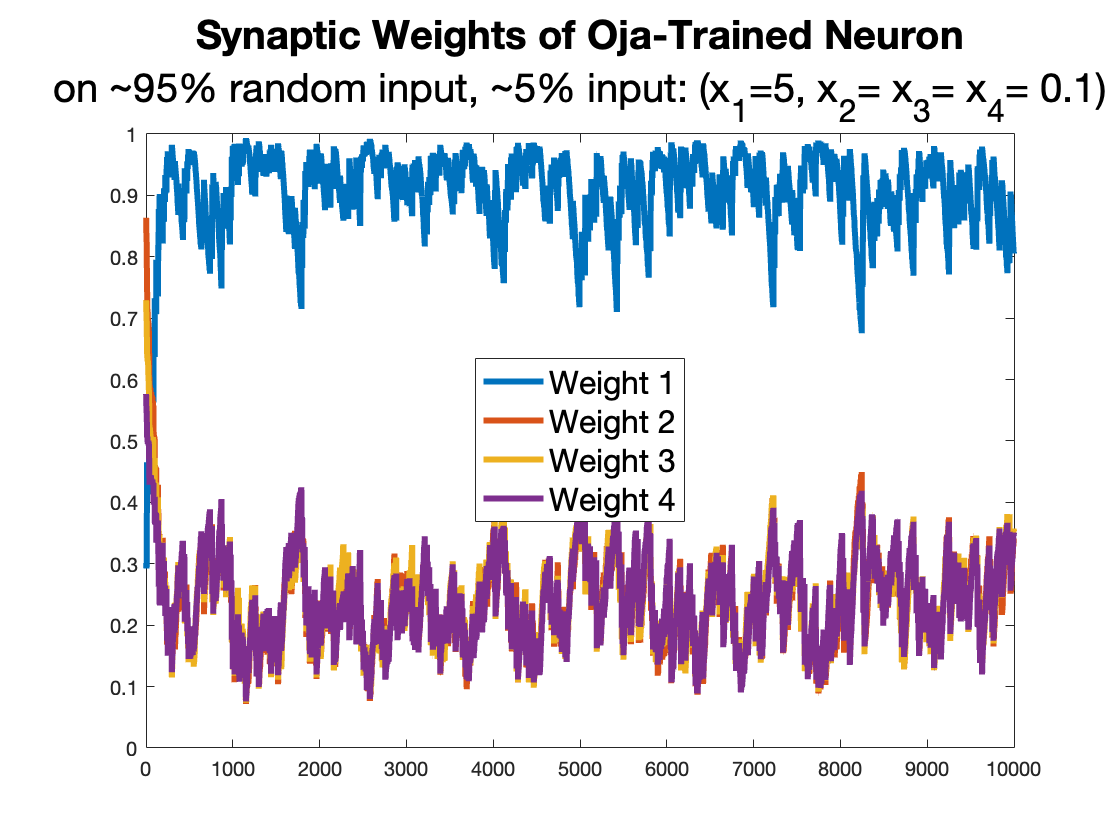

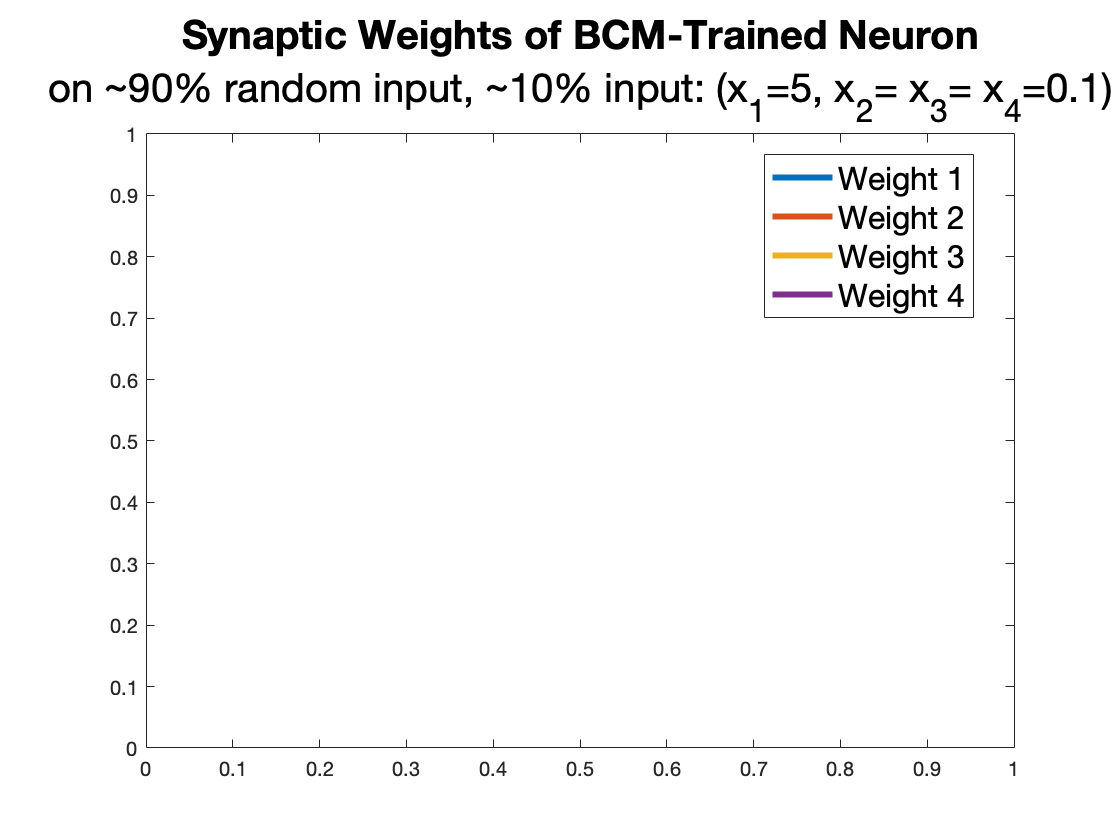

figure;
for p = 1:4
    plot(1:n_iters, oja_history(p,:), 'LineWidth', 3);
    hold on;
end
title("Synaptic Weights of Oja-Trained Neuron", "FontSize", 20)
subtitle("on ~95% random input, ~5% input: (x_1=5, x_2= x_3= x_4= 0.1)", "FontSize",20)
legend("Weight 1", "Weight 2", "Weight 3", "Weight 4", "FontSize", 16, "location", "best")

### Patterned/Noise/Patterned Input

The last simulation stimulates the neuron with solely patterned input then noise for the remainder,  after enough time, the neurons are occasionally triggered by the pattern again to test their abilities to recall it.

% Define parameters
eta = 10^-3
n_iters = 10000; 

% initialize all weights the same

eta = 1.0000e-03

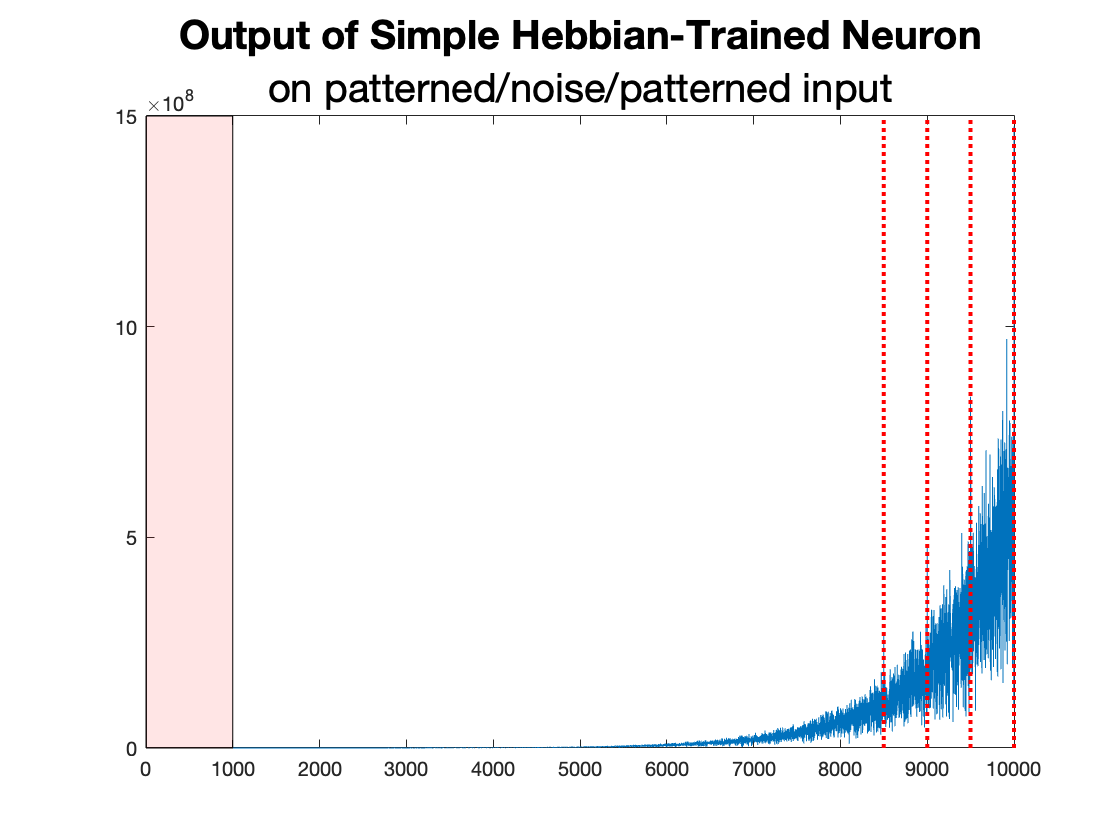

w_hebb = rand([4 1]);
w_oja = w_hebb;

% For keeping track of output
oja_out = NaN(n_iters,1);
hebb_out = NaN(n_iters,1);
BCM_out = NaN(n_iters,1);

% for keeping track of weights
hebb_history = NaN([4, n_iters]);
oja_history = NaN([4, n_iters]);
BCM_history = NaN([4, n_iters]);

%SIMULATE
for i = 1:n_iters
    if i < 1000  % For the first 1000 iterations, give the neuron patterned input
        x = [5; 0.1; 0.1; 0.1];
    elseif (i > 4 * n_iters / 5 && mod(i, 500) == 0) 
       % After 4/5ths of the way through the timulation, occasionally give
       % it that input again
        x = [5;0.1;0.1;0.1];
    else % In between those sections, feed the neuron solely random input
        x = rand([4 1]);
    end
    
    % Update the hebbian parameters:
    y_hebb = w_hebb' * x;
    hebb_out(i) = y_hebb;
    w_hebb = hebbian(w_hebb, x, y_hebb, eta);
    hebb_history(:,i) = w_hebb;
    
    % Update the Oja parameters:
    y_oja = w_oja' * x;
    oja_out(i) = y_oja;
    w_oja = oja(w_oja, x, y_oja, eta);
    oja_history(:,i) = w_oja;
    
end
% Plot the outputs of the neurons
figure;
plot(1:n_iters, hebb_out);
hold on;
% The code for creating a red box to highlight when the neuron receives
% patterned input:
yl = ylim;
patch([0 0 1000 1000], [yl(1) yl(2) yl(2) yl(1)], 'white', 'FaceColor', 'red', 'FaceAlpha', 0.1);
% The code for the red lines showing where it receives instances of
% patterned input:
plot([8500 8500], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([9000 9000], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([9500 9500], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([10000 10000], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
title("Output of Simple Hebbian-Trained Neuron", "FontSize", 20)
subtitle("on patterned/noise/patterned input", "FontSize", 20)
figure;
hold on;
plot(1:n_iters, oja_out);

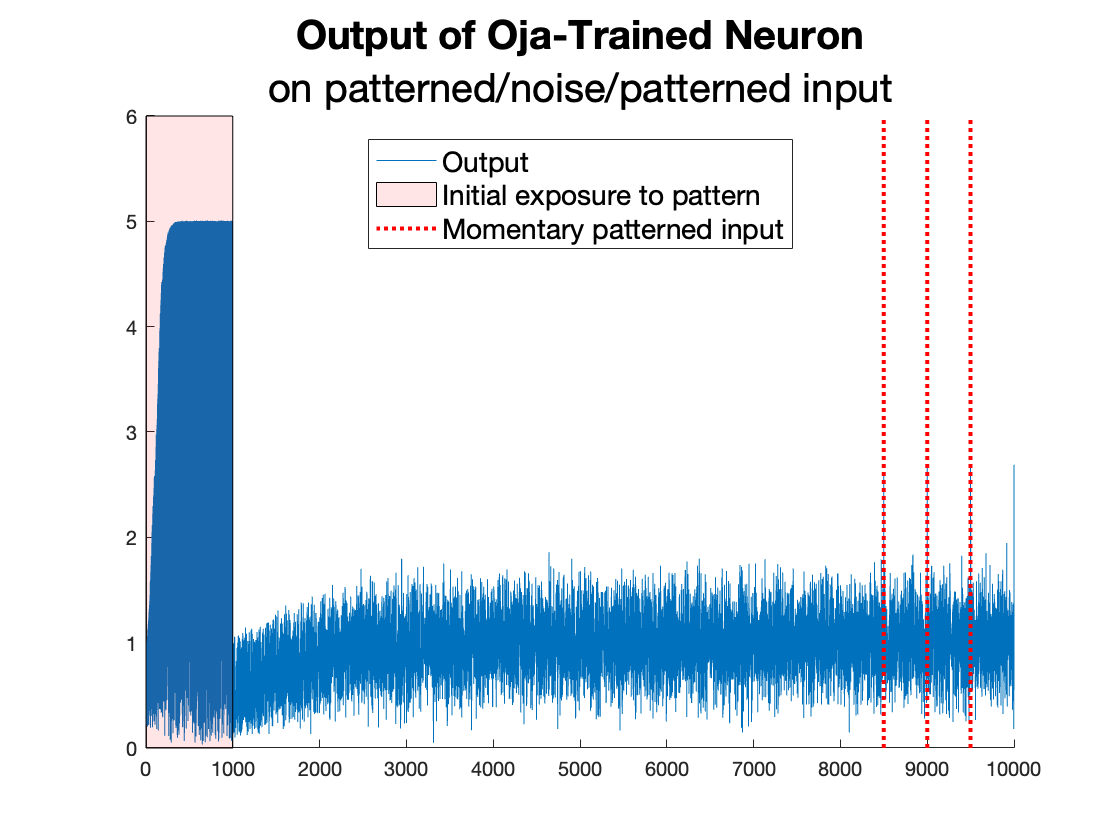

yl = ylim;
patch([0 0 1000 1000], [yl(1) yl(2) yl(2) yl(1)], 'white', 'FaceColor', 'red', 'FaceAlpha', 0.1);
plot([8500 8500], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([9000 9000], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([9500 9500], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
legend("Output", "Initial exposure to pattern", "Momentary patterned input", 'Location',"best", 'FontSize', 14);
title("Output of Oja-Trained Neuron", "FontSize", 20)
subtitle("on patterned/noise/patterned input", "FontSize", 20)

% Plots for the weights of the neurons over time: 
figure;

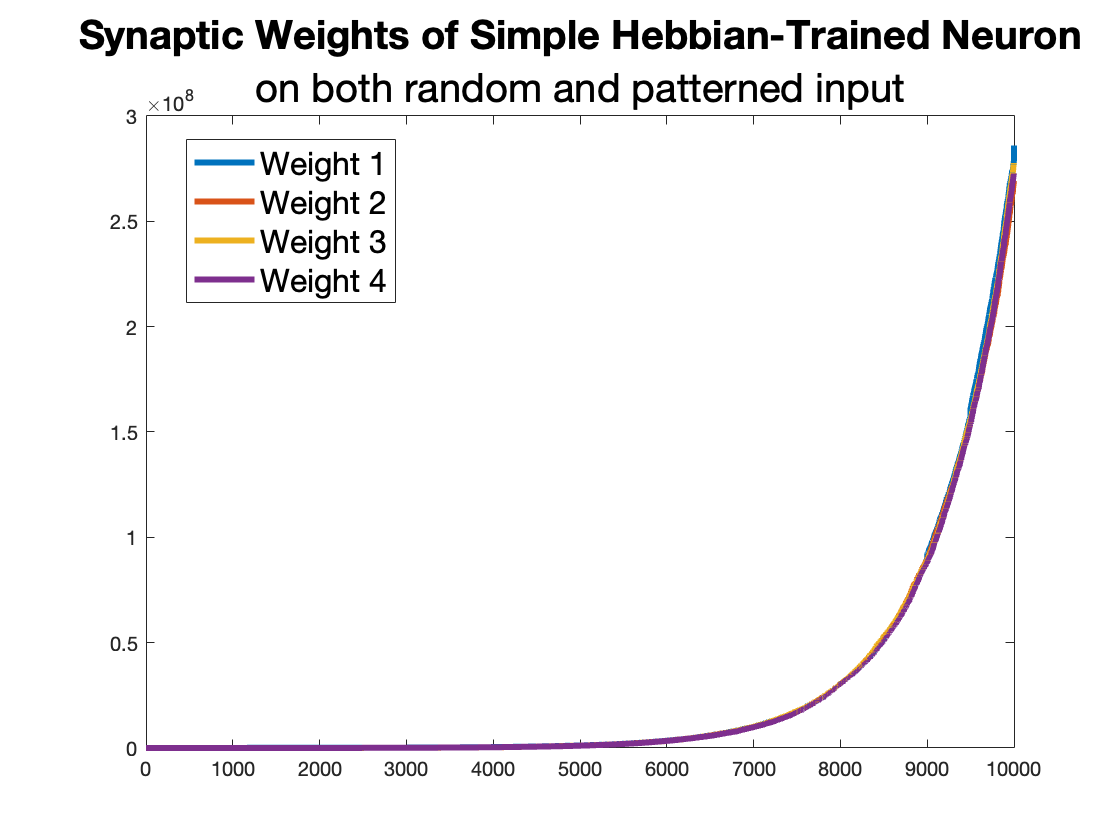

for p = 1:4
    plot(1:n_iters, hebb_history(p,:), 'LineWidth', 3);
    hold on;
end
title("Synaptic Weights of Simple Hebbian-Trained Neuron", "FontSize", 20)
subtitle("on both random and patterned input", "FontSize",20)
legend("Weight 1", "Weight 2", "Weight 3", "Weight 4", "FontSize", 16, "location", "best")
figure;
for p = 1:4
    plot(1:n_iters, oja_history(p,:), 'LineWidth', 3);

    hold on;
end
yl = ylim;
patch([0 0 1000 1000], [yl(1) yl(2) yl(2) yl(1)], 'white', 'FaceColor', 'red', 'FaceAlpha', 0.1);
plot([8500 8500], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([9000 9000], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([9500 9500], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
title("Synaptic Weights of Oja-Trained Neuron", "FontSize", 20)
subtitle("on both random and patterned input", "FontSize",20)
legend("Weight 1", "Weight 2", "Weight 3", "Weight 4", "Initial exposure to pattern", "Momentary patterned input", "FontSize", 16, "location", "best")

% The weight update function for the Simple Hebbian Rule

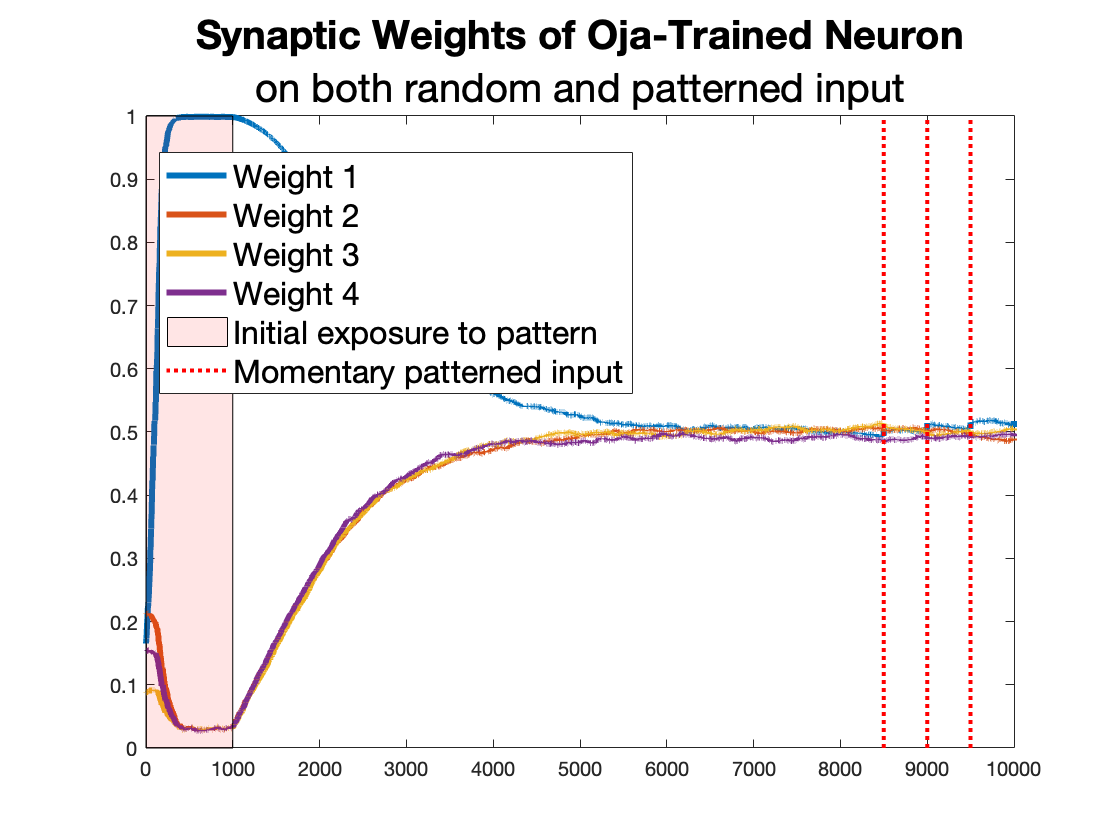

function [new_weight] = hebbian(w,x,y,eta)
    new_weight = w + eta .* x .* y;

end
% The weight update function for Oja's Rule
function [new_weight] = oja(w,x,y,eta)
    new_weight = w + eta * (y .* x - (y^2 .* w));
end